% Prepare data
% Process new TGA data from text file and store in DTGdata_all.mat
% Nanta
% 2021-2022

% In the DTGdata_all.mat, the variable with "_wet" is before removing
% drying zone (<105 °C). The varaible used for fitting is the one without
% "_wet" which contain data from temperature above 105 C.

clear variables


## 1. Load data


% load data from file
Initial_folder = pwd

Initial_folder = 'G:\My Drive\P5_Batch_potato_exp\TGA_potato_peel'

[file,path] = uigetfile('*.txt')

file = 'BarkPine_20Cpmin_N2_R2.txt'

path = 'G:\My Drive\P5_Batch_potato_exp\TGA_potato_peel\TGA_data\'

cd(path);
A = readmatrix(file);     % A() = time (min), temperature (°C), weight (mg) , ... others 

% get sample size (initial wet weight)
fid = fopen(file,'rt')

fid = 3

allstr = textscan(fid,'%s', 'Delimiter', '\n');
allstr = allstr{1};

expend = strncmp(allstr,'Size',4);
rowexp = find(expend);
temp = char(allstr(rowexp))

temp = 'Size	8.55100	mg'

sample_size = str2double(temp(6:12))

sample_size = 8.5510


expend = strncmp(allstr,'Sample',6)

expend = 2005×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


rowexp = find(expend);
temp = char(allstr(rowexp))

temp = 'Sample	Bark'

sample_name = temp(8:end)

sample_name = 'Bark'

fclose(fid);

%%%%% Change heating rate and name of data here
Heating_rate = 20

Heating_rate = 20

BarkPine_20Kpm_R2_wet = Prepare_data2(A(:,1),A(:,2),A(:,3),Heating_rate, sample_size, sample_name);

Initial weight 8.550864 
Wet sample


dryweight = 7.6839

StructS = struct with fields:
    dryweight: 7.6839


Moisture 10.139159 
Char 33.441758

%OakExtFree_20Kpm_R2

% add to 'DTGdata_biomass.mat'
cd(Initial_folder);
save('DTGdata_biomass.mat','BarkPine_20Kpm_R2_wet','-append');


h7 = figure;


window =

  0×0 empty char array



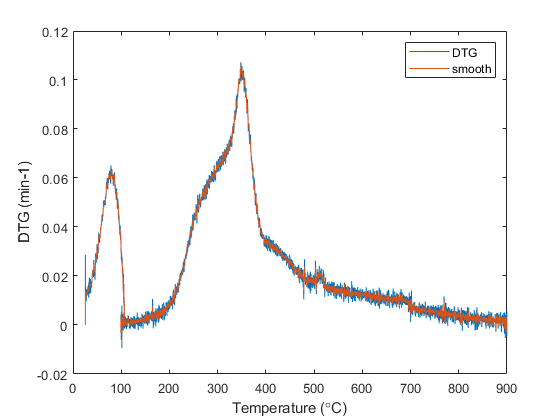

plot(BarkPine_20Kpm_R2_wet.T,BarkPine_20Kpm_R2_wet.DTG,BarkPine_20Kpm_R2_wet.T,yy)
legend('DTG','smooth')
xlabel('Temperature (\circC)')
ylabel('DTG (min-1)')

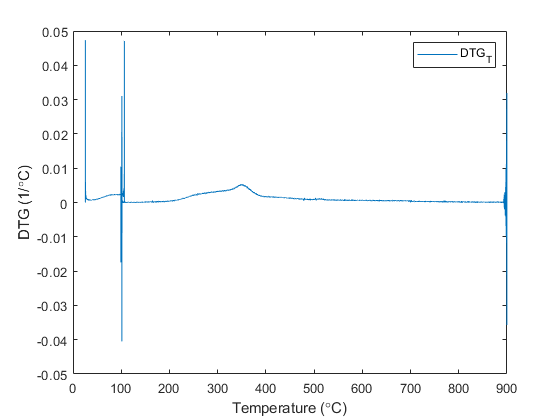

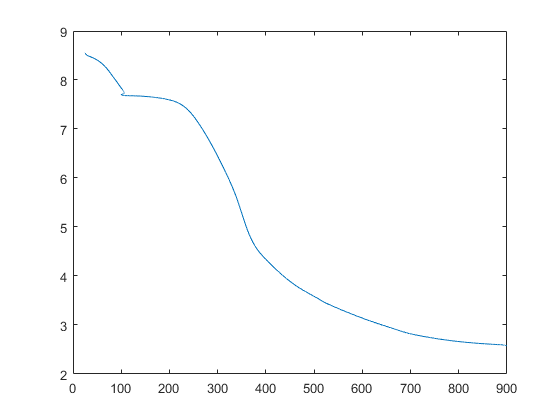


h6 = figure;
plot(BarkPine_20Kpm_R2_wet.T,BarkPine_20Kpm_R2_wet.DTG_T)
legend('DTG_T')
xlabel('Temperature (\circC)')
ylabel('DTG (1/\circC)')

## F1-2: Prepare_data2 **- Function to calculate DTG from experimental data**

- take in data from file 

function structS = Prepare_data2(time, T, W, heating_rate, sample_size,sample_name)

structS.time = time;
structS.T = T;
structS.W = W;
structS.beta = heating_rate;
structS.wetWeight = sample_size;
structS.name = sample_name;

W_volatile = W(1) - W(end);     % Total volatile (mg)

structS.X(1,1) = 1;
structS.DTG(1,1) = 0;
TempDAlpha_T(1,1) = 0;
for i=2:length(time)
    structS.X(i,1) = (W(i)-W(end))/W_volatile;       % Volatile fraciton left, X = 1-Alpha
    structS.DTG(i,1) = (structS.X(i-1,1)-structS.X(i,1))/(time(i)-time(i-1)); % DTG = -dX/dt
    structS.Alpha(i,1) = (W(1)-W(i))/W_volatile;     % conversion, Alpha = 1-X
    structS.DAlpha(i,1) = (structS.Alpha(i,1)-structS.Alpha(i-1,1))/(structS.time(i)-structS.time(i-1));

    if (structS.T(i)-structS.T(i-1)) < 0.001
        structS.DTG_T(i,1) = 0;                      % DTG_T is -dX/dT, calulated but not use
        TempDAlpha_T(i,1) = 0;
    else
        structS.DTG_T(i,1) = (structS.X(i-1,1)-structS.X(i,1))/(structS.T(i)-structS.T(i-1));
        TempDAlpha_T(i,1) = (structS.Alpha(i,1)-structS.Alpha(i-1,1))/(structS.T(i)-structS.T(i-1));
    end
end

structS.DAlpha_T = smooth(TempDAlpha_T);

%%% moisture and char (dry basis)
fprintf('Initial weight %f \n',structS.W(1))
if structS.W(1) < 0.999*structS.wetWeight
    disp('Dry sample')
    structS.moisture = 0;
    structS.char = 100*structS.W(end)/structS.W(1);
else
    % moisture = weight different at the beginning (W(1)) and at 105 degC
    disp('Wet sample')
    
    % get position where T = 105 degC
    i_T105_start = 1000;
    while structS.T(i_T105_start) < 104.99
        i_T105_start = i_T105_start+1;
    end
    i_T105_end = i_T105_start;
    while structS.T(i_T105_end) < 106
        i_T105_end = i_T105_end+1;
    end
    % dry weight is the average value between T=105-106 degC
    dryweight = mean(structS.W(i_T105_start:i_T105_end))
    StructS.dryweight = dryweight
    
    structS.moisture = 100*(structS.W(1) - dryweight)/structS.W(1);
    structS.char = 100*structS.W(end)/dryweight;
end

fprintf('Moisture %f \n',structS.moisture)
fprintf('Char %f',structS.char)


end
